A =  [1 0; 0 1]; % valori paper: A = eye(2);
B = [0;0]; % valori paper: B = 0;
C =  [cos(2*pi*60*t), -sin(2*pi*60*t)];  % frequenza di 60Hz
D = 0;


plant = ss(A, B, C, D, Ts);  %Ts perchè è discreto

Fc = 60; %frequency 60Hz
Av =1;  % amplitude
Ts = 0.0005; % 1/0.0005 = 2 kHz  campionamento
StopTime = 0.1;             % seconds
t = (0:Ts:StopTime-Ts)';     % seconds
%x1 = 1.087*cos(3.249);
%x2 = 1.087*sin(3.249);
x1 = 1*cos(0);
x2 = 1*sin(0);
signal = x1*cos(2*pi*Fc*t) - x2*sin(2*pi*Fc*t); % y (outout plant)


Plant senza input noise:

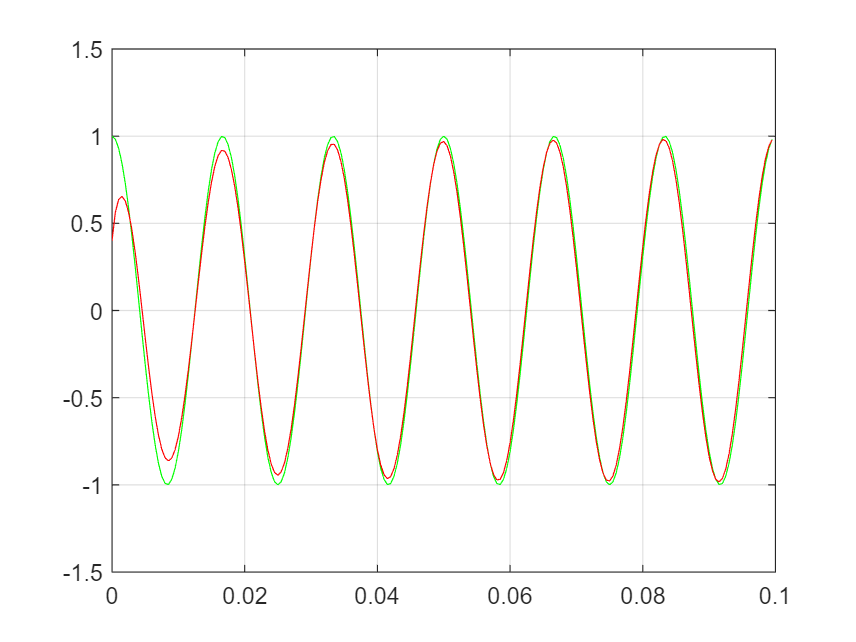

Q = [0.0001, 0;0, 0.0001];
R = 1.5;


filtered = funzioneBella(signal, Q, R, 0.1);
plot(t, signal, 'green', t, filtered, 'red');
ylim([-1.5,1.5]);
grid on;

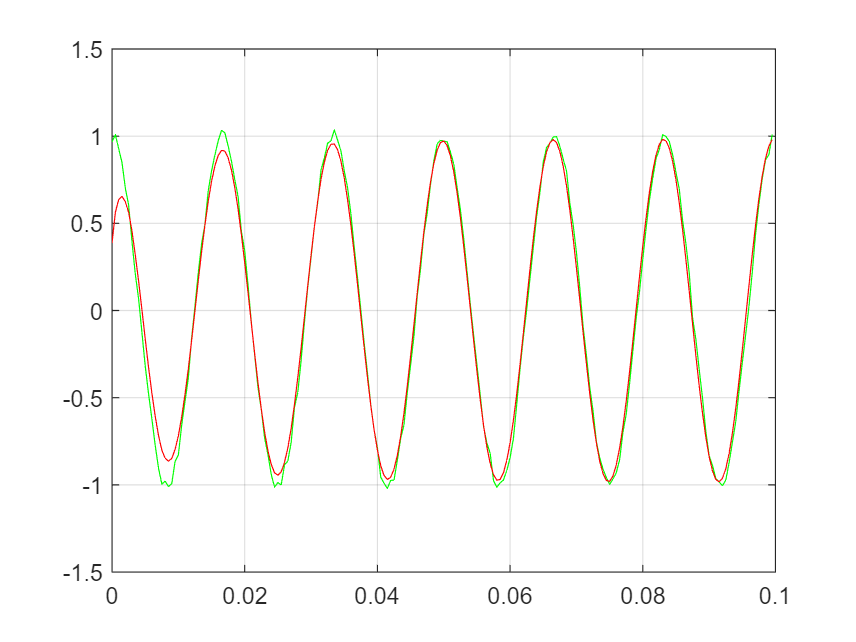


noise = randn(size(signal));
signal_disturbed = signal + 0.02 * noise; 

[filtered, residue] = funzioneBella(signal_disturbed, Q, R, 0.1);
plot(t, signal_disturbed, 'green', t, filtered, 'red');
ylim([-1.5,1.5]);
grid on;

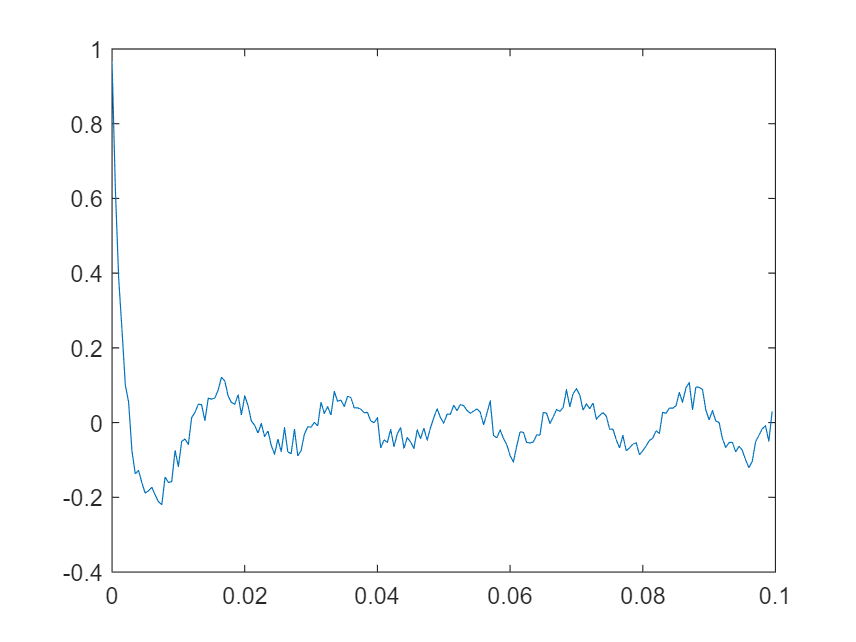


plot(t, residue);

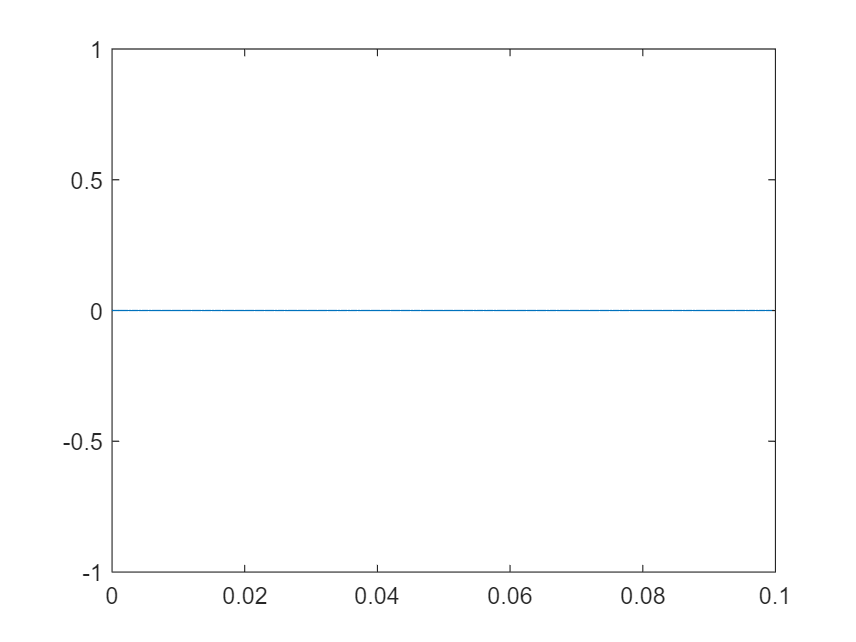




g = residue' * resi_cov * residue;

plot(t, g);

function [ x, y, K_m, P_m ] = kalman_filter( sysd, u, w, z, t, x_0, P_0, R, Q )
% discrete-time model
F = sysd.a;
G = sysd.b(:,1);
H = sysd.c;
J = sysd.b(:,2:end);
% initialization
k = 1 +1;
x = x_0;                 
P = P_0;
I = diag( ones(length(F),1) );
K_m = []; P_m = [];
%%%%%%%%%%%%%%%%%%%%%%%%%%%% kalman filter %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
for n = 1:length(t)-1
    % 1. prediction
    x(:,k) = F*x(:,k-1) +G*u(k-1) +J*w(:,k-1);  % 'a priori' predicted state
    P      = F*P*F' +J*Q*J';                    % 'a priori' predicted covariance
    % 2. correction
    K      = P*H'*inv( H*P*H' +R );             % computes optimal gain   
    e(k)   = z(k) -H*x(:,k);                    % measurement residual
    x(:,k) = x(:,k) +K*e(k);                    % 'a posteriori' state estimative 
    P      = (I -K*H)*P;                        % 'a posteriori' covariance
    
    y(k)   = H*x(:,k);                          % estimated output
    k      = k +1;                              
    
    K_m    = [K_m K];                           % stores current K
    P_m    = [P_m P];                           % stores current P            
end
x = transpose(x);
end